%% ES115 Module 3 Project: Smart Home Energy Dashboard
% Team: Mike, Will
% Project 1: Smart Home Energy Analysis

clear; clc; close all;

%% 1. Data Import (Competency C8)
% Check if data exists, if not, create a dummy set for demonstration
filename = 'energy_data.csv';

if ~isfile(filename)
    % Generating 21 days (3 weeks) of synthetic hourly data
    days = reshape(repmat(1:21, 24, 1), [], 1);
    hours = repmat((0:23)', 21, 1);
    usage = 0.5 + 3*rand(size(days)) + (hours > 17 & hours < 21)*2; % Higher usage in evening
    T = table(days, hours, usage, 'VariableNames', {'Day', 'Hour', 'Usage_kWh'});
    writetable(T, filename);
    fprintf('Generated synthetic dataset: %s\n', filename);
end

Generated synthetic dataset: energy_data.csv



data = readtable(filename);

%% 2. Data Cleaning & Metrics (Competency C1, C2)
% Check for missing values
data.Usage_kWh(isnan(data.Usage_kWh)) = 0; 

% Compute metrics
total_usage = sum(data.Usage_kWh);
avg_hourly = mean(data.Usage_kWh);
peak_load = max(data.Usage_kWh);

% Find peak hour (Task 2)
[val, idx] = max(data.Usage_kWh);
peak_hour_time = data.Hour(idx);

fprintf('--- Energy Metrics ---\n');

--- Energy Metrics ---


fprintf('Total Usage: %.2f kWh\n', total_usage);

Total Usage: 1126.10 kWh


fprintf('Average Hourly: %.2f kWh\n', avg_hourly);

Average Hourly: 2.23 kWh


fprintf('Peak Load: %.2f kWh at hour %d\n', peak_load, peak_hour_time);

Peak Load: 5.46 kWh at hour 19



%% 3. Weekday vs Weekend Analysis (Competency C7)
% Assuming Day 1-5 are weekdays, 6-7 are weekends in a 7-day cycle
data.IsWeekend = mod(data.Day, 7) == 0 | mod(data.Day, 7) == 6;

weekday_data = data.Usage_kWh(data.IsWeekend == 0);
weekend_data = data.Usage_kWh(data.IsWeekend == 1);

avg_weekday = mean(weekday_data);
avg_weekend = mean(weekend_data);

%% 4. Interventions - "What-If" Analysis (Competency C5)
% Intervention 1: Reduce peak evening load by 15%
% Intervention 2: Shift 10% of total load to off-peak
reduction_factor = 0.85; 
[new_total, savings] = calculate_savings(data.Usage_kWh, reduction_factor);

fprintf('\n--- Intervention Results ---\n');


--- Intervention Results ---


fprintf('Potential New Total: %.2f kWh\n', new_total);

Potential New Total: 1009.46 kWh


fprintf('Total Savings: %.2f kWh\n', savings);

Total Savings: 116.64 kWh


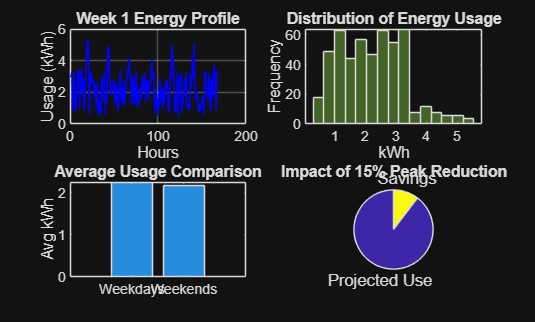


%% 5. Visualization Dashboard (Competency C6)
figure('Name', 'Smart Home Energy Dashboard', 'NumberTitle', 'off');

% Plot 1: Time Series (Hourly usage for first week)
subplot(2,2,1);
plot(data.Usage_kWh(1:168), 'LineWidth', 1, 'Color', 'b');
title('Week 1 Energy Profile');
xlabel('Hours');
ylabel('Usage (kWh)');
grid on;

% Plot 2: Histogram of Usage
subplot(2,2,2);
histogram(data.Usage_kWh, 15, 'FaceColor', [0.4 0.6 0.2]);
title('Distribution of Energy Usage');
xlabel('kWh');
ylabel('Frequency');

% Plot 3: Weekday vs Weekend Comparison
subplot(2,2,3);
bar([avg_weekday, avg_weekend]);
set(gca, 'XTickLabel', {'Weekdays', 'Weekends'});
title('Average Usage Comparison');
ylabel('Avg kWh');

% Plot 4: Summary Dashboard (Visualizing Savings)
subplot(2,2,4);
pie([new_total, savings], {'Projected Use', 'Savings'});
title('Impact of 15% Peak Reduction');

% Save the figure for the report
saveas(gcf, 'energy_dashboard.png');